load motivation file

clear
m = imread('motive.png'); 
m = flipud(m);

szm = size(m)

szm =    637   521     3


szm = szm([2 1])

szm =    521   637


ctm = szm/2

ctm =   260.5000  318.5000


Draw Canvas


im = imshow(m)

im =   Image - 속성 있음:

           CData: [637×521×3 uint8]
    CDataMapping: 'direct'

  모든 속성 표시



im.AlphaData = .1

im =   Image - 속성 있음:

           CData: [637×521×3 uint8]
    CDataMapping: 'direct'

  모든 속성 표시


axis on
ax = gca()

ax =   Axes - 속성 있음:

             XLim: [0.5000 521.5000]
             YLim: [0.5000 637.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1266 0.1002 0.7454 0.8667]
            Units: 'normalized'

  모든 속성 표시


ax.YDir = "normal"

ax =   Axes - 속성 있음:

             XLim: [0.5000 521.5000]
             YLim: [0.5000 637.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1266 0.1002 0.7454 0.8667]
            Units: 'normalized'

  모든 속성 표시


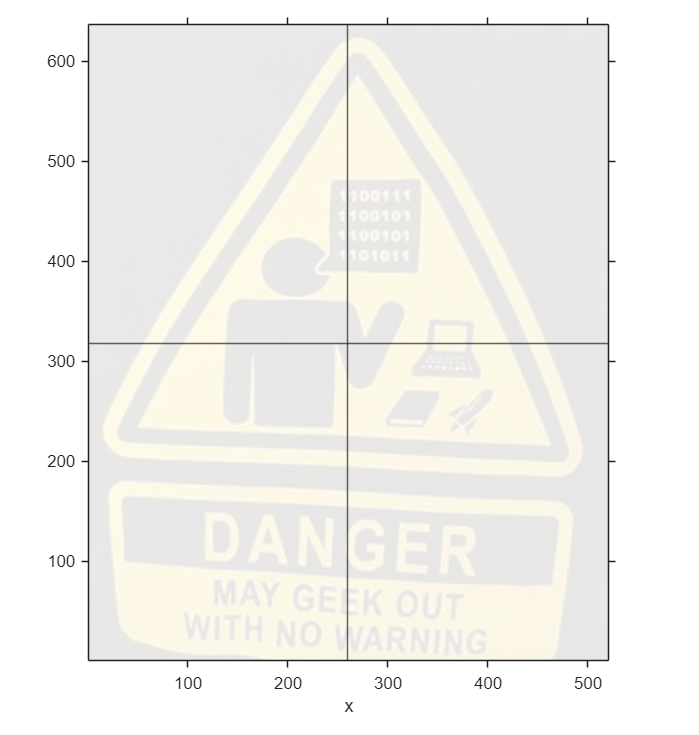

xline(ctm(1))
yline(ctm(2))
xlabel('x')

Draw upper Triangle

l = 250;
tht = pi*[0 2/3 4/3] +pi/2;
xo = l*cos(tht);
yo = l*sin(tht);
xc = ctm(1)

xc = 260.5000

yc = ctm(2)

yc = 318.5000

ut = plg2(xo,yo,xc,yc)

ut = v = 

  polyshape - 속성 있음:

      Vertices: [3×2 double]
    NumRegions: 1
      NumHoles: 0


v = 

  polyshape - 속성 있음:

      Vertices: [3×2 double]
    NumRegions: 1
      NumHoles: 0

  plg2 - 속성 있음:

    xShape: [1.5308e-14 -216.5064 216.5064]
    yShape: [250 -125.0000 -125.0000]
     xCntr: 260.5000
     yCntr: 318.5000
     polyO: [1×1 polyshape]
     polyT: [1×1 polyshape]


ut.polyO

v =   polyshape - 속성 있음:

      Vertices: [3×2 double]
    NumRegions: 1
      NumHoles: 0


ans =   polyshape - 속성 있음:

      Vertices: [3×2 double]
    NumRegions: 1
      NumHoles: 0


ut.polyT

v =   polyshape - 속성 있음:

      Vertices: [3×2 double]
    NumRegions: 1
      NumHoles: 0


ans =   polyshape - 속성 있음:

      Vertices: [3×2 double]
    NumRegions: 1
      NumHoles: 0


v =   polyshape - 속성 있음:

      Vertices: [3×2 double]
    NumRegions: 1
      NumHoles: 0


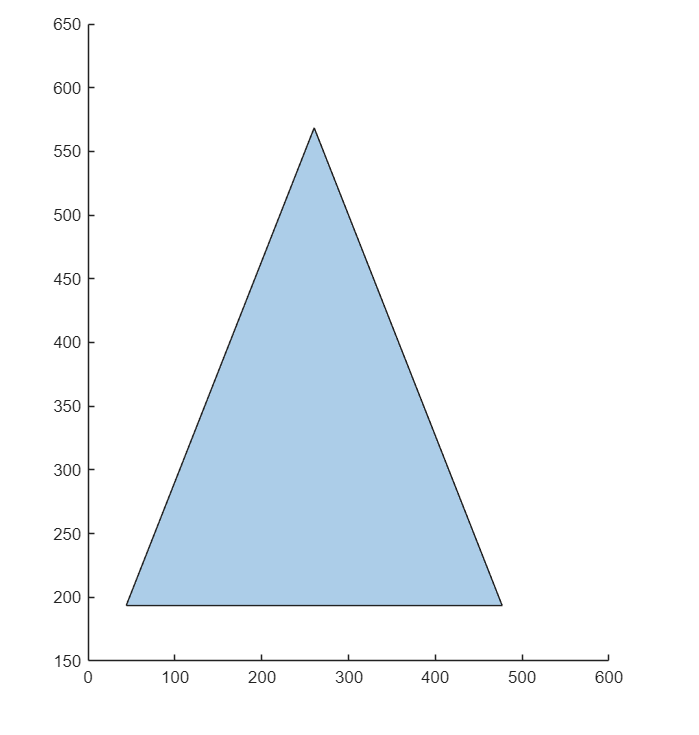

ans =   Polygon - 속성 있음:

    FaceColor: [0.0660 0.4430 0.7450]
    FaceAlpha: 0.3500
    EdgeColor: [0.1294 0.1294 0.1294]
    LineWidth: 0.5000
    LineStyle: '-'
        Shape: [1×1 polyshape]

  모든 속성 표시


hold on
ut.plot()

hold off

Draw lower rectengle

lrec = l*sqrt(3)
x = [1 -1 -1 1]*lrec/2 + ctm(1)

lrec = 433.0127

y = .2*[1 1 -1 -1]*lrec/2 + ctm(2) - l

x =   477.0064   43.9936   43.9936  477.0064


lr = polyshape(x,y)

y =   111.8013  111.8013   25.1987   25.1987


hold on

lr =   polyshape - 속성 있음:

      Vertices: [4×2 double]
    NumRegions: 1
      NumHoles: 0


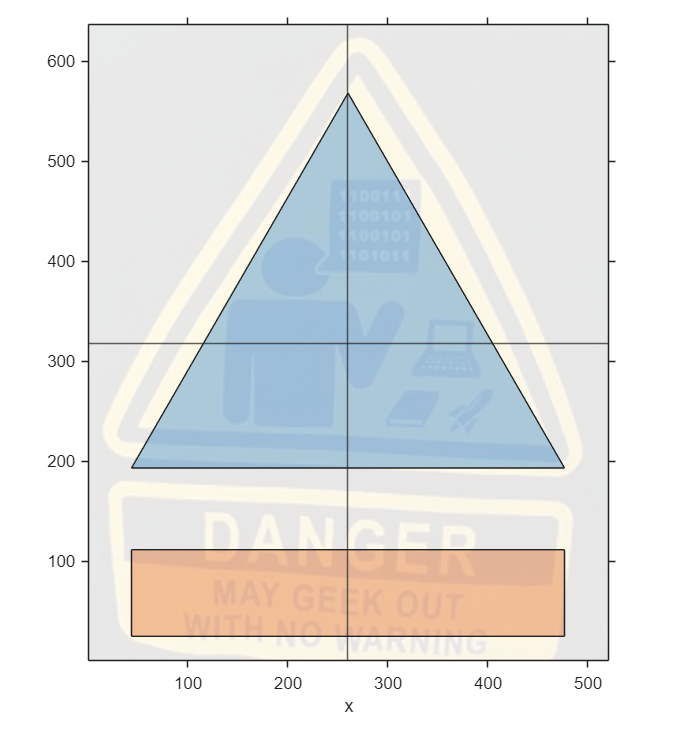

plot(lr)
hold off